**Introduction**

This script is to test channel estimation ability of our OTFS toolbox,

clear;
clc;

**Case 1: *****Overflow*** on the Doppler axis

In this example, we need 8+8+1=17 grids on the Doppler axis while we only have 16 grids. Therefore, you should observe an exception.

%% OTFS settings
nSubcarNum = 256/2;
nTimeslotNum = 32/2;
% channel
p = 6;
kmax = 3.5;
lmax = 14;
% pilot & data
SNR_d = 10;                                 % data SNR range (dB)
SNR_p = 10;                                 % pilot SNR (dB) (we have the condition of)
No = 1;                                     % noise power (linear)
% pilot
pil_pow = 10.^(SNR_p./10);
pilots_num_delay = 1;
pilots_num_doppl = 1;
guard_delay_num_neg = lmax;
guard_delay_num_pos = lmax;
guard_doppl_num_neg = 8;
guard_doppl_num_pos = 8;
% signal
sig_pow = 10.^(SNR_d./10);
sig_len = nSubcarNum*nTimeslotNum - (pilots_num_delay+guard_delay_num_neg+guard_delay_num_pos)*(pilots_num_doppl+guard_doppl_num_neg+guard_doppl_num_pos);
% Tx Settings
M_mod = 16;
M_bits = log2(M_mod);
sympool_norm = qammod(0: M_mod-1, M_mod, 'UnitAveragePower',true);

%% Symbols
% xDD_syms
nbits = randi([0,1],sig_len*M_bits,1);
xDD_syms = sqrt(sig_pow/2)*qammod(nbits, M_mod,'InputType','bit','UnitAveragePower',true);

%% RG
rg = OTFSResGrid(nSubcarNum, nTimeslotNum);
try
    rg.map(xDD_syms, "pilots_num_delay", pilots_num_delay, "pilots_num_doppl", pilots_num_doppl, "pilots_pow", pil_pow, "guard_delay_num_neg", guard_delay_num_neg, "guard_delay_num_pos", guard_delay_num_pos, "guard_doppl_num_neg", guard_doppl_num_neg, "guard_doppl_num_pos", guard_doppl_num_pos);
catch err
    disp(err.message);
end

Overflow on the Doppler axis (pilots + guards is over timeslot number).


**Case 2: **All pilots allocation for ***center pilots*** and ***reduced guard*** (***integer Doppler***)

Please note that there is no noise used in this example.

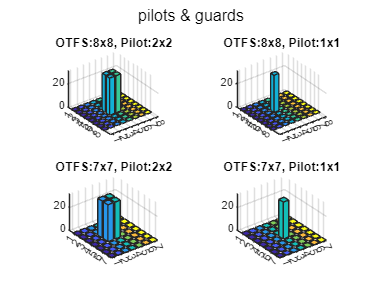

SNR_p = 30; % dB
SNR_d = 10; % dB
No = 0;
% No = 1;
pil_pow = 10^(SNR_p/10);
pil_thr = 0;
% pil_thr = 3*sqrt(1/pil_pow);
sig_pow = 10^(SNR_d/10);
M_mod = 4;
M_bits = log2(M_mod);
sympool = sqrt(sig_pow)*qammod(0: M_mod-1, M_mod, 'UnitAveragePower',true);
p = 2;
lmax = 1;
kmax = 1;
guard_delay_num_neg = lmax;
guard_delay_num_pos = lmax;
guard_doppl_num_neg = kmax*2;
guard_doppl_num_pos = kmax*2;
% OTFS & pilots settings
N = [8 8 7 7];
M = [8 8 7 7];
pilots_num_delay = [2 1 2 1];
pilots_num_doppl = [2 1 2 1];
% pilots & guards
figure("name", "pilots & guards");
for set_id = 1:length(M)
    symbols_len = N(set_id)*M(set_id)-(pilots_num_delay(set_id)+guard_delay_num_neg+guard_delay_num_pos)*(pilots_num_doppl(set_id)+guard_doppl_num_neg+guard_doppl_num_pos);
    symbols = zeros(symbols_len, 1);
    % build rg
    rg = OTFSResGrid(M(set_id), N(set_id));
    rg.map(symbols, "pilots_num_delay", pilots_num_delay(set_id), "pilots_num_doppl", pilots_num_doppl(set_id), "pilots_pow", pil_pow, "guard_delay_num_neg", guard_delay_num_neg, "guard_delay_num_pos", guard_delay_num_pos, "guard_doppl_num_neg", guard_doppl_num_neg, "guard_doppl_num_pos", guard_doppl_num_pos);
    % plot
    subplot(2,2,set_id);
    bar3(abs(rg.getContent()));
    title("OTFS:" + string(N(set_id)) + "x" + string(M(set_id)) + ", Pilot:" + string(pilots_num_doppl(set_id)) + "x" + string(pilots_num_delay(set_id)));
end
sgtitle("pilots & guards");

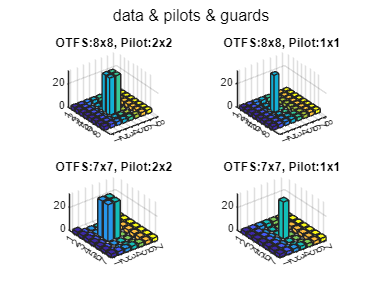

% data & pilots & guards
figure("name", "data & pilots & guards");
for set_id = 1:length(M)
    symbols_len = N(set_id)*M(set_id)-(pilots_num_delay(set_id)+guard_delay_num_neg+guard_delay_num_pos)*(pilots_num_doppl(set_id)+guard_doppl_num_neg+guard_doppl_num_pos);
    nbits = randi([0 1], symbols_len*M_bits, 1);
    symbols = sqrt(sig_pow)*qammod(nbits, M_mod,'InputType','bit','UnitAveragePower',true);
    % build rg
    rg = OTFSResGrid(M(set_id), N(set_id));
    rg.map(symbols, "pilots_num_delay", pilots_num_delay(set_id), "pilots_num_doppl", pilots_num_doppl(set_id), "pilots_pow", pil_pow, "guard_delay_num_neg", guard_delay_num_neg, "guard_delay_num_pos", guard_delay_num_pos, "guard_doppl_num_neg", guard_doppl_num_neg, "guard_doppl_num_pos", guard_doppl_num_pos);
    % plot
    subplot(2,2,set_id);
    bar3(abs(rg.getContent()));
    title("OTFS:" + string(N(set_id)) + "x" + string(M(set_id)) + ", Pilot:" + string(pilots_num_doppl(set_id)) + "x" + string(pilots_num_delay(set_id)));
end
sgtitle("data & pilots & guards");

% all after channel
figure("name", "data & pilots & guards");
for set_id = 1:length(M)
    symbols_len = N(set_id)*M(set_id)-(pilots_num_delay(set_id)+guard_delay_num_neg+guard_delay_num_pos)*(pilots_num_doppl(set_id)+guard_doppl_num_neg+guard_doppl_num_pos);
    nbits = randi([0 1], symbols_len*M_bits, 1);
    symbols = sqrt(sig_pow)*qammod(nbits, M_mod,'InputType','bit','UnitAveragePower',true);
    % build rg
    rg = OTFSResGrid(M(set_id), N(set_id));
    rg.map(symbols, "pilots_num_delay", pilots_num_delay(set_id), "pilots_num_doppl", pilots_num_doppl(set_id), "pilots_pow", pil_pow, "guard_delay_num_neg", guard_delay_num_neg, "guard_delay_num_pos", guard_delay_num_pos, "guard_doppl_num_neg", guard_doppl_num_neg, "guard_doppl_num_pos", guard_doppl_num_pos);
    rg.pulse2Recta();
    % through the channel
    otfs = OTFS();
    otfs.modulate(rg);
    otfs.setChannel(p, lmax, kmax);
    % plot
    %subplot(2,2,set_id);
    %bar3(abs(rg.X_DD));
    %title("OTFS:" + string(N(set_id)) + "x" + string(M(set_id)) + ", Pilot:" + string(pilots_num_doppl(set_id)) + "x" + string(pilots_num_delay(set_id)));
end




